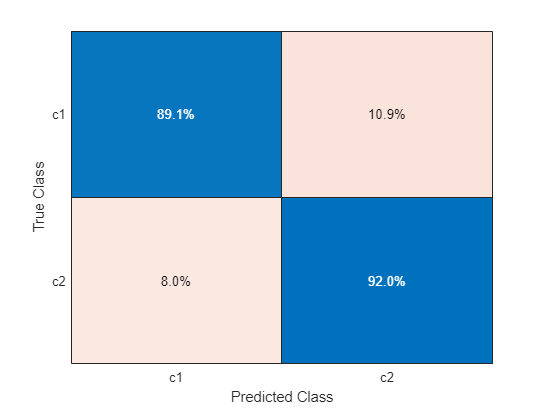

N1 = 1000;
N2 = 100;
d = 5;
mu1 = 1;
mu2 = 0;
X1 = randn(N1, d) + mu1;
X2 = randn(N2, d)*0.8 + mu2;
X2(:, 1) = X2(:, 1) + 0.8 * X2(:, 2);
X = [X1;X2];
y = string([repmat("c1", N1, 1); repmat("c2", N2, 1)]);

cls = Discriminant(0.5, "quadratic", 0.3);
cls.fit(X, y, struct("c1", 0.6, "c2", 0.4));
yhat = cls.predict(X);
confusionchart(y, yhat, "Normalization","row-normalized")